clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
% Something wrong with pump; replaced pump before cast 9
% no CTD alignment seems to work best? Was there a pump? 
% Casts 
cast09 = readSBScnv( 'AR21_009_hyst.cnv' );
cast10 = readSBScnv( 'AR21_010_hyst.cnv' );
cast11 = readSBScnv( 'AR21_011_hyst.cnv' );
cast12 = readSBScnv( 'AR21_012_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')

btl = readtable('Irminger_Sea-04_AR21_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year4')
btl10 = readtable('AR21_010_hyst.csv','TextType','string');

btl11 = readtable('AR21_011_hyst.csv','TextType','string');

btl12 = readtable('AR21_012_hyst.csv','TextType','string');


% Join tables 
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");

clear btl0* btl1* btl2*

btlsum_yr4 = [btlsum10; btlsum11; btlsum12];
btlsum0 = btlsum_yr4; %

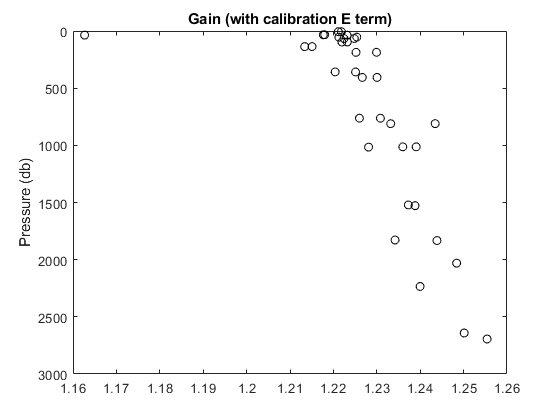

figure
plot(btlsum_yr4.Winkler_mLL./btlsum_yr4.Sbeox0ML_L,btlsum_yr4.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

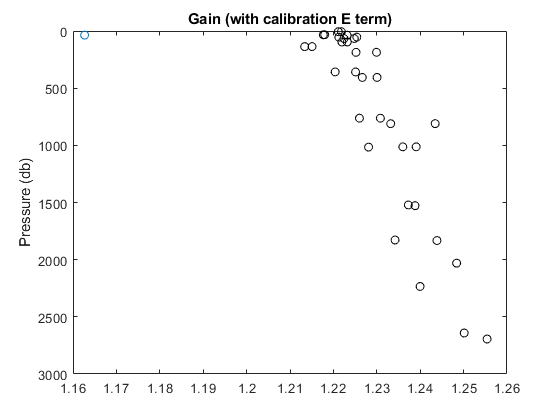

gain0_threshold = 1.2;
gain0 = btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L;
Wink_out = find(gain0 < gain0_threshold);
btlsum0.Winkler_mLL(Wink_out) = NaN;

figure
plot(btlsum_yr4.Winkler_mLL./btlsum_yr4.Sbeox0ML_L,btlsum_yr4.PrDM,'o')
hold on
plot(btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.61240e-001);
cal.VOFFSET = double(-5.10000e-001);
cal.A = double(-5.44340e-003);
cal.B = double(3.01750e-004);
cal.C = double(-4.29640e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.04000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0930';
cal.OCALDATE = '11-Nov-16';

H = [-0.033, 5000, 1450]; % Default 

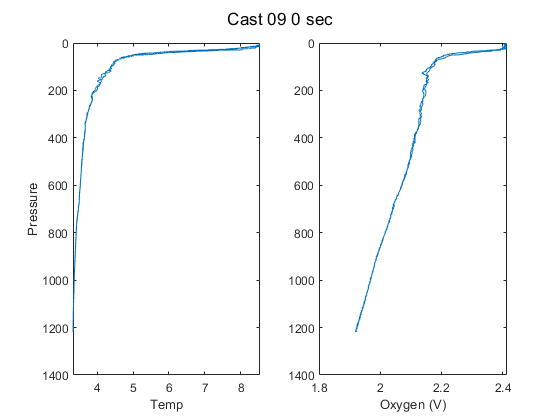

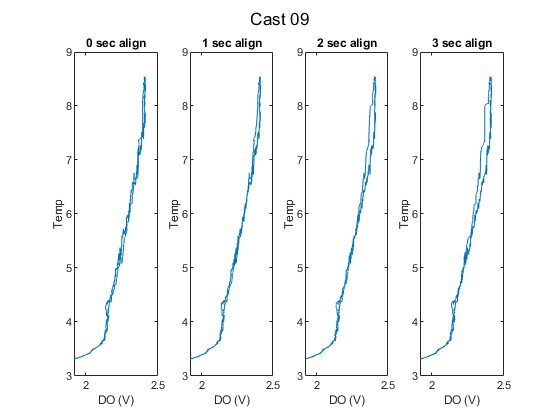

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 1; a2 = 2; a3 = 3;

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

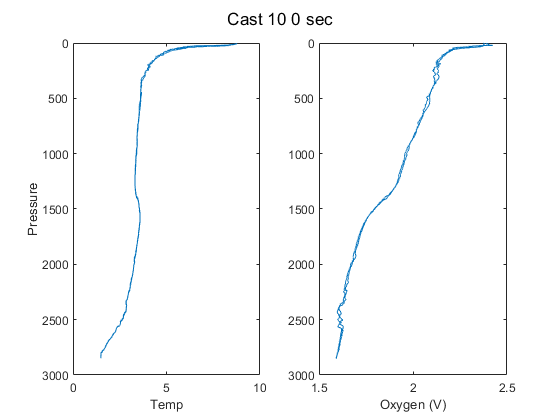

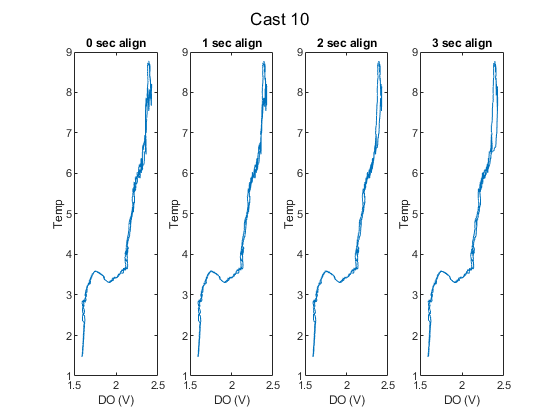

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

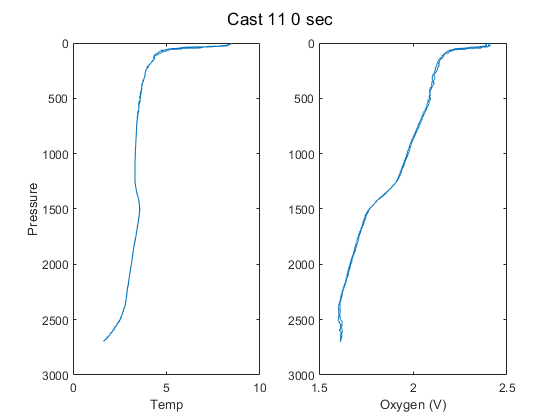

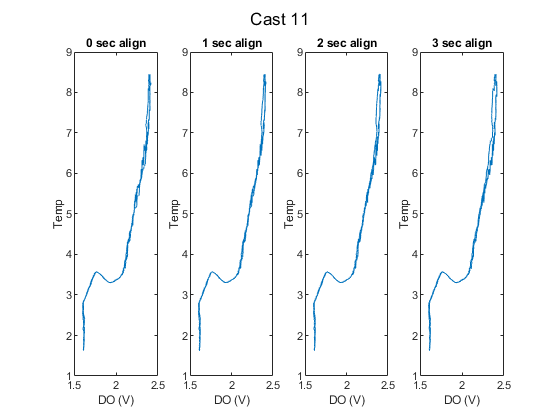

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

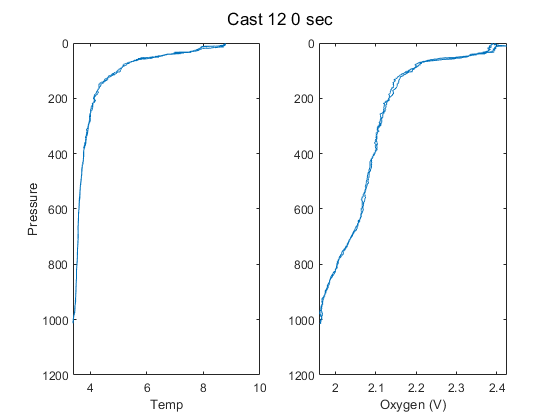

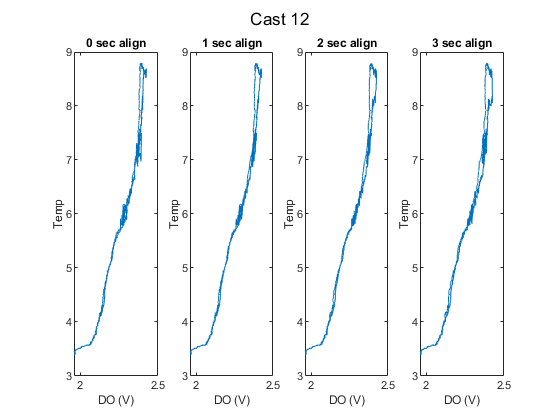

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);


% Pick align_sec

align_sec = 0; 


% Read in processed casts
% Processed with 0 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
cast09 = readSBScnv( 'uAR21_009_hyst_abcdefg.cnv' );
cast10 = readSBScnv( 'uAR21_010_hyst_abcdefg.cnv' );
cast11 = readSBScnv( 'uAR21_011_hyst_abcdefg.cnv' );
cast12 = readSBScnv( 'uAR21_012_hyst_abcdefg.cnv' );

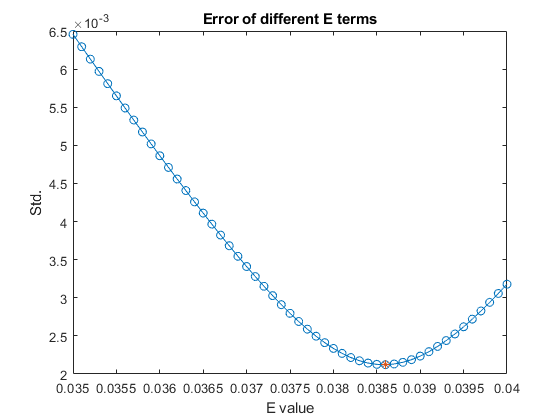

cal.E2 = 0.0386


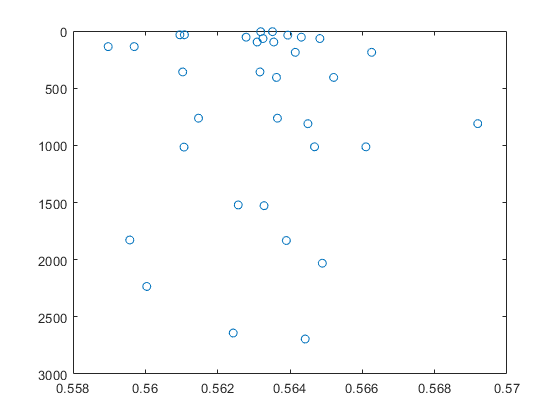

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
[cal] = E2_calculation(btlsum0,cal); % Use dummy bottle summary with outlier removed

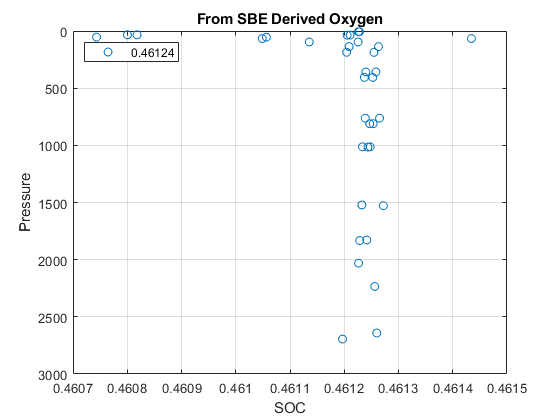

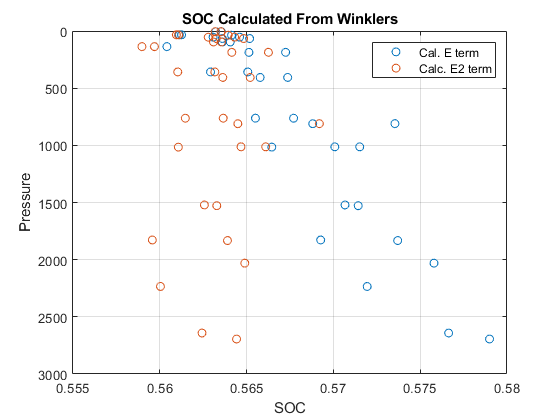

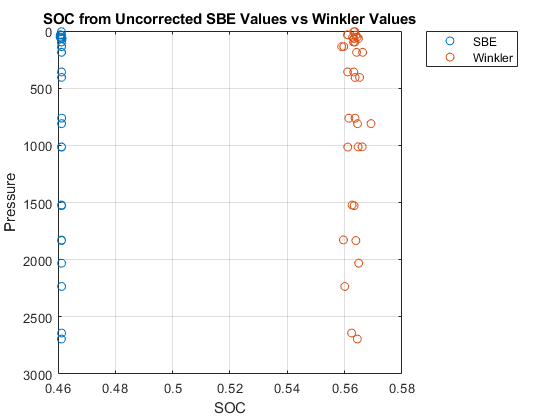

New SOC = 0.56319
EGain = 1.221+/- 0.0046009


[cal] = Gain_E2_Calculation(btlsum0,cal); % Use dummy bottle summary with any outliers removed

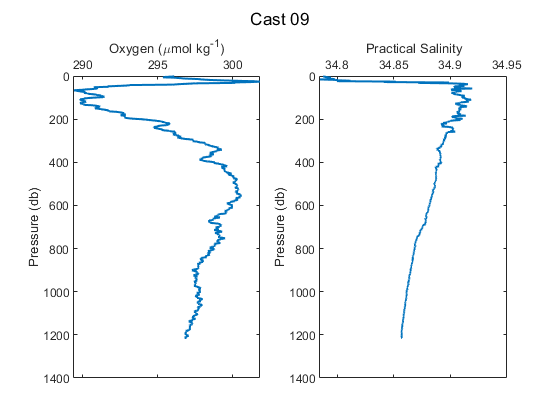

[cast09, btlsum09] = Process_Cast_Gain_E2(cast09,cal,0,1,'Cast 09');

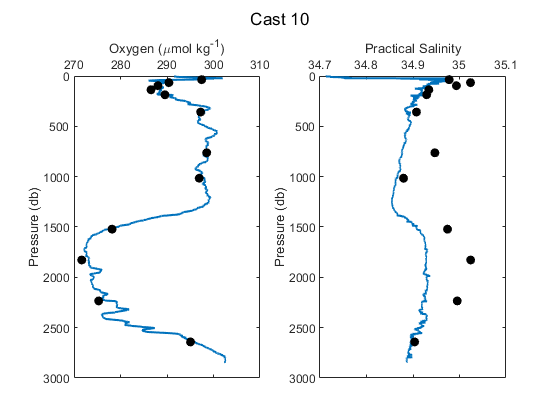

[cast10, btlsum10] = Process_Cast_Gain_E2(cast10,cal,btlsum10,1,'Cast 10');

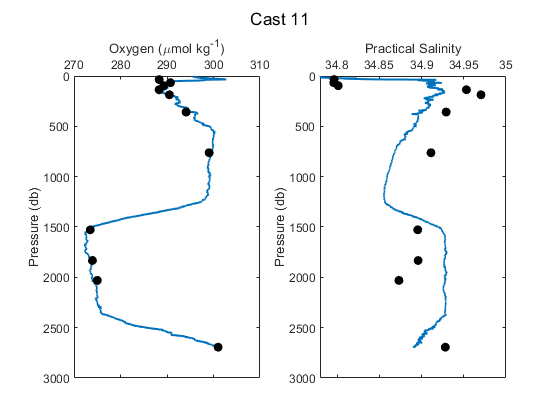

[cast11, btlsum11] = Process_Cast_Gain_E2(cast11,cal,btlsum11,1,'Cast 11');

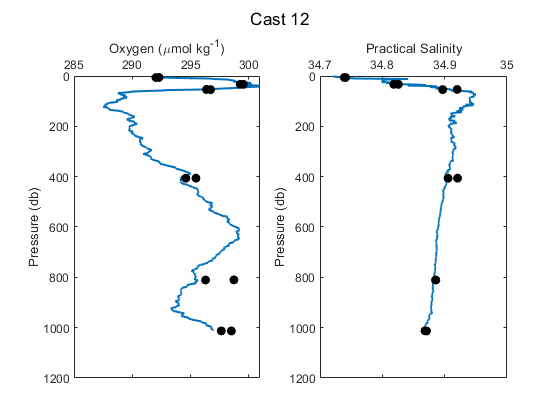

[cast12, btlsum12] = Process_Cast_Gain_E2(cast12,cal,btlsum12,1,'Cast 12');

btlsum_yr4 = [btlsum10; btlsum11; btlsum12];

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 0


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0386


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.46124


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.56319


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.221+/- 0.0046009


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')
clear btlsum0
dt_Processed = datetime;
save Year4_Processed_KF cast* btl* cal* dt_Processed 